%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                         %
%                   LAB 1 - ASEN 2004                     %
%                   Aircraft Analysis                     %
%                                                         %
%                                                         %
%        This script analyzes *SOMETHING* for the         %
%                    B747 and Tempest UAS.                %
%                                                         %
%                      01/20/2021                         %
%                                                         %
%                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Set Environment

clear
clc

## Declare and Define the B747 Variables

B747_S = 511;                       % Boeing 747 Planform Area [m^2]
B747_AR = 7;                        % Boeing 747 Aspect Ratio [unitless]
B747_Re = 1000000;                  % Boeing 747 Reynold's Number [unitless]

% Create the Variable Array for the B747
B747_vars = [B747_AR,B747_Re,B747_S];

% Boeing 747  Table Data [AOA C_l C_d]
B747 = [-5 -0.3505 0.00953;
        -4 -0.2514 0.00852;
        -3 -0.1493 0.00741;
        -2 -0.0318 0.00584;
        -1 0.0912 0.0055;
         0 0.2133 0.00509;
         1 0.3048 0.00506;
         2 0.318  0.00743;
         3 0.3925 0.00948;
         4 0.4889 0.01033;
         5 0.5855 0.01132;
         6 0.6808 0.01256;
         7 0.7744 0.01441;
         8 0.8721 0.01634;
         9 0.9729 0.02052;
        10 1.061  0.02498;
        11 1.1263 0.03112;
        12 0.9165 0.07156;
        13 0.7781 0.14138];

## Declare and Define the Tempest UAS Variables

Tempest UAS Reynold's Number

Tempest_Re = 200000;

% Tempest UAS Table Data [AOA C_l C_d]
Tempest = [-5 -0.4166 0.04049;
            -4 -0.2734 0.02;
            -3 -0.125 0.01439;
            -2 0.0032 0.01054;
            -1 0.2136 0.00976;
             0 0.3312 0.00933;
             1 0.4263 0.00906;
             2 0.5241 0.00898;
             3 0.6236 0.00928;
             4 0.7217 0.0101;
             5 0.8165 0.01133;
             6 0.9059 0.01314;
             7 0.9889 0.01573;
             8 1.0582 0.02012;
             9 1.1042 0.02723;
            10 1.1555 0.03641;
            11.25 1.1303 0.05193;
            12 1.097 0.06243];

## Calculate the C_L for the B747

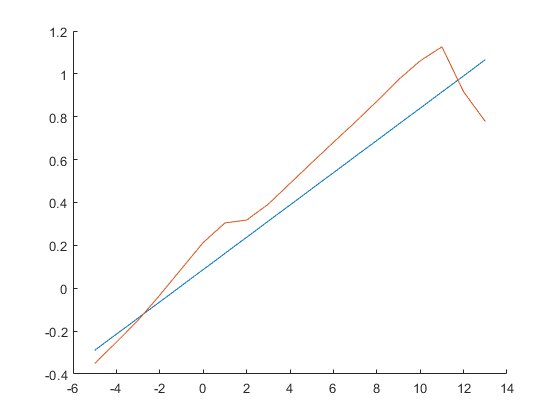

[B747_C_L,B747_C_D] = finiteWingLift(B747,B747_vars,2,10);

hold on
plot(B747(:,1),B747_C_L);
plot(B747(:,1),B747(:,2));
hold off

## Functions

% finiteWingLift
%
% Function that calculates the 3D finite wing 3D lift coefficient and 3D wing
% drag polar
%
% @param data The table data that includes the AOA, C_l, and the C_d in
%               that order.
%

function [C_L,C_D_wing] = finiteWingLift(data,vars,aoa_one,aoa_two)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Get the slope of the linear portion of the 2D lift curve from airfoil data
    linearFit = polyfit(data(data(data(:,1)<aoa_two,1)>aoa_one,1),data(data(data(:,1)<aoa_two,1)>aoa_one,2),1);
    
    % Set the slope of 2D airfoil curve as a_0 according to convention
    a_0 = linearFit(1);
    
    % Define the Span Efficiency factor
    e = 0.9;
    
    % Define a the lift curve slope
    a = a_0/(1+((57.3*a_0)/(pi*e*AR)));
    
    % Get the C_l where the AOA equal 0
    alpha_aoa_0 = data(data(:,1)==0,2);
    
    % Calculate C_L for all AOA
    C_L = a*(data(:,1)-alpha_aoa_0)+linearFit(2);
    
    % Calculate C_D_wing
    C_D_wing = data(:,3) + (C_L.^2)/(pi*e*AR);
end